**Data import, d = 3 mm**

clear;
filename = 'Bender Solenoid test';
sheetname1 = '3mm disp. new fixed point';
data = readmatrix(filename,'Sheet',sheetname1);

**Voltage and Energy output of each Resistance**

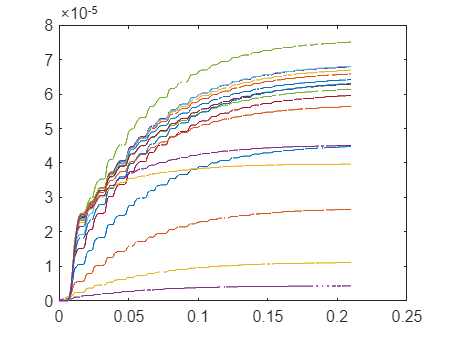

clf
Power_all = zeros(1,ceil(size(data,2)/10));
Energy_all = zeros(1,ceil(size(data,2)/10));
Resistor = zeros(1,ceil(size(data,2)/10));
for i = 1:ceil(size(data,2)/10)
    Resistor(i) = data(1,10*i-9); %Resistor's value of each loop
    [energy_avg, sum_Energy_avg, power_avg, time] = data2energyBender(data(:,10*i-9:10*i),Resistor(i)); %at each R
    Energy_all(i) = sum_Energy_avg;
    Power_all(i) = power_avg;

    plot(time,energy_avg)
    hold on
end
hold off


%plot(time,energy_avg)

**Power and Voltage output vs. Resistance**

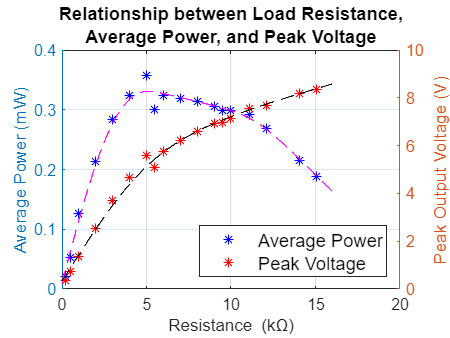

clf
[Resistor_sorted, idx] = sort(Resistor);
Resistor_sorted = Resistor_sorted*1e-3; % [kOhm]
Power_all_sorted = Power_all(idx) .* 1e3; % Power output in [mW] unit
Energy_all_sorted = Energy_all(idx) .*1e3; % Energy output in [mJ] unit
volt_max = transpose(data(3,1:10:end-9));
volt_max_sorted = volt_max(idx);

%fit curve
yyaxis left;
load enso
Power_R = fit(transpose(Resistor_sorted),transpose(Power_all_sorted),'smoothingspline','SmoothingParam',0.5);
plot(transpose(Resistor_sorted),transpose(Power_all_sorted),'*b')
hold on
plot(Power_R,'m')
ylabel('Average Power (mW)')
hold off

yyaxis right;
volt_R = fit(transpose(Resistor_sorted),volt_max_sorted,'smoothingspline','SmoothingParam',0.1);
plot(transpose(Resistor_sorted),volt_max_sorted,'*r')
hold on
plot(volt_R,'k')
hold off
ylabel('Peak Output Voltage (V)')

%xlim([0,20000])
legend('Average Power','','Peak Voltage','Location','southeast','Fontsize',11)
%legend('Power','Voltage','Location','eastoutside')
xlabel('Resistance (k\Omega)')
title({'Relationship between Load Resistance,';'Average Power, and Peak Voltage'},'FontSize',11)
grid on

## **This part is for a presentation slide**

**Voltage-time response (R = 5451 Ohm, D = 3 mm, d = 439 um)**

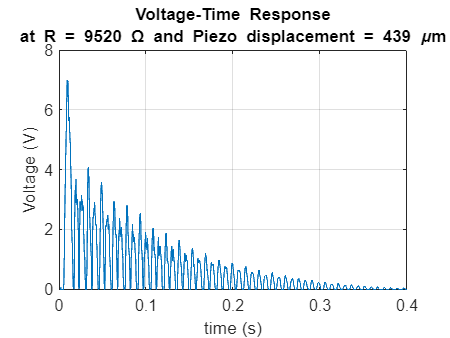

clf
voltage_pre_slide = data(:,123);
time_pre_slide = data(:,122) - 0.41;
R_pre_slide = data(1,121);
plot(time_pre_slide,voltage_pre_slide)
xlim([0,0.4])
xlabel('time (s)')
ylabel('Voltage (V)')
title({'Voltage-Time Response'; ['at R = ' num2str(R_pre_slide) ' \Omega and Piezo displacement = 439 \mum']})
grid on

**Energy-time response (R = 5451 Ohm, D = 3 mm, d = 439 um)**

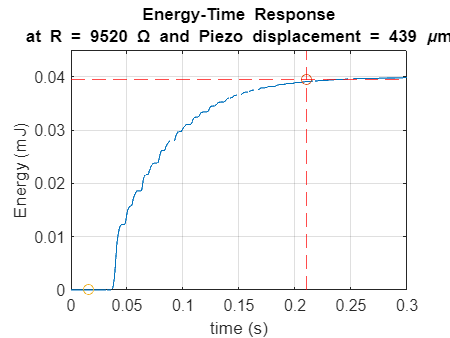

clf
[energy_avg_pre_slide, sum_Energy_avg_pre_slide, power_avg_pre_slide, time] = data2energyBender(data(:,41:50),R_pre_slide);
plot(time,energy_avg_pre_slide *1e3)
xlim([0 0.3])
ylim([0 0.045])
xlabel('time (s)')
ylabel('Energy (mJ)')
title({'Energy-Time Response'; ['at R = ' num2str(R_pre_slide) ' \Omega and Piezo displacement = 439 \mum']})
grid on

hold on
xline(0.21,'--r')
yline(0.0395,'--r')
plot(0.21,0.0395,'o')
plot(0.016,0,'o')

% xline(0.0466,'g')